# comparing the CJF visual classification to pilot

We compare the zooniverse classification ( designated as CJF: cosmic jellyfish) to the expert classification in the 2 pilot projects (TNG100  - Yun 2019 & TNG50) on the object matched subsample. 

## perliminaries

global illUnits
global DEFAULT_MATFILE_DIR

## load CJF sample

load([DEFAULT_MATFILE_DIR '/cosmic_jellyfish_objectTable.mat'])
objectCJF=objectTable;

objectCJF.score(objectCJF.score>20)=20;

% % deal with TNG50 funky galaxies 
% funkySnaps=[ 33 40 50 67 72 78];
% funkyTNG50.snap33=[21560, 50698, 90630, 127581, 138654];
% funkyTNG50.snap40= [102, 126, 158, 36250, 66110, 112204, 163074];
% funkyTNG50.snap50=79623;
% funkyTNG50.snap67=356638;
% funkyTNG50.snap72=91931;
% funkyTNG50.snap78=[226474, 451164];
% 
% for snp=funkySnaps
%     
%     funkyList=funkyTNG50.(['snap' num2str(snp)]);
%     for sid=funkyList
%         tempTab=table(0,"TNG50",snp,sid,0,0,0,...
%     'variableNames',{'subject_ids','sim','snap','subfind','clsNum','score','scoreTotal'});
%     objectCJF=[objectCJF;tempTab];
%         
%     end
% end
% 
% % deal with TNG100 funky galaxies 
% funkySnaps=[50 59];
% funkyTNG100.snap50=10011;
% funkyTNG100.snap59=[301337, 301338];
% for snp=funkySnaps
%     
%     funkyList=funkyTNG100.(['snap' num2str(snp)]);
%     for sid=funkyList
%         tempTab=table(0,"TNG100",snp,sid,0,0,0,...
%     'variableNames',{'subject_ids','sim','snap','subfind','clsNum','score','scoreTotal'});
%     objectCJF=[objectCJF;tempTab];
%         
%     end
% end


## Load Yun2019 sample

Generated a table of objects based on the flag catalogs in the post-processing folder.


load([DEFAULT_MATFILE_DIR '/yun19_jellyfish_objectTable.mat'])
object100=objectTable;

## load TNG50 pilot sample

load([DEFAULT_MATFILE_DIR '/jf_objectTable_TNG50.mat'])
load([DEFAULT_MATFILE_DIR '/jellyfishScores_TNG50.mat'])
objectTNG50=objectTable;



## compare TNG50 to CJF

Selected the objects in the CJF sample which appear in the TNG50 pilot project. Matching is based on Subfind ID and sanpshot and of course, simulation. 

A normalized score between 0 and 1 is given to each object. 

The normalization of the CJF project is 20, so the possible scores are (votes on the left, normalized score on the right) : 

% scrTab=table(,'VariableNames',{'score','normalized score'});
% head(scrTab,21)
aa=cat(2,(0:20)',(0:20)'./20);
disp(aa)

         0         0
    1.0000    0.0500
    2.0000    0.1000
    3.0000    0.1500
    4.0000    0.2000
    5.0000    0.2500
    6.0000    0.3000
    7.0000    0.3500
    8.0000    0.4000
    9.0000    0.4500
   10.0000    0.5000
   11.0000    0.5500
   12.0000    0.6000
   13.0000    0.6500
   14.0000    0.7000
   15.0000    0.7500
   16.0000    0.8000
   17.0000    0.8500
   18.0000    0.9000
   19.0000    0.9500
   20.0000    1.0000



The normalization of the TNG50 pilo project is 6, so the possible scores are : 

aa=cat(2,(0:6)',(0:6)'./6);
disp(aa)

         0         0
    1.0000    0.1667
    2.0000    0.3333
    3.0000    0.5000
    4.0000    0.6667
    5.0000    0.8333
    6.0000    1.0000





% find subsample 

mask50=(objectCJF.sim=="TNG50");
indCJF50=zeros(height(objectTNG50),1)-1;

for j=1:height(objectTNG50)
    subID=objectTNG50.subfind(j);
    snp=objectTNG50.snap(j);
    
    ind=find(objectCJF.snap==snp & objectCJF.subfind==subID & mask50);
    if ~isempty(ind)
        indCJF50(j)=ind;
    end
end

indMask50=indCJF50>0;


scoreCJF50=min(objectCJF.score(indCJF50(indMask50))./20,1);
score50=tally6(indMask50)./6;

fprintf('Size of TNG50 pilot sample: %i \n',height(objectTNG50))

Size of TNG50 pilot sample: 3469 


fprintf('Number of objects in Pilot program found in CJF: %i \n',sum(indMask50) )

Number of objects in Pilot program found in CJF: 3466 


Most of the objects in the pilot program are found in the CJF sample - we can try and track down the missing 3 objects and see why they're missing . 

fprintf('Objects missing in the CJF sample: \n')

Objects missing in the CJF sample: 



missingTab=table(objectTNG50.subfind(~indMask50),objectTNG50.snap(~indMask50),'VariableNames',{'subfind','snap'})

missingTab = 3×2 table
     subfind      snap
    __________    ____

    2.8623e+05     40 
     2.891e+05     50 
    4.9902e+05     99 


head(missingTab,8);

## Compare the JF by scores for the two projects 

We plot the comparison between the scores of the two classification projects in bins. The following plot shows the precentage of objects in each score bin. An object is in a bin if it is greater or equal to the lower limit and lower than the higher limit. Only for the top bin (0.8-1.0) objects are higher or equal to 0.8 and lower or equal to 1.0. 

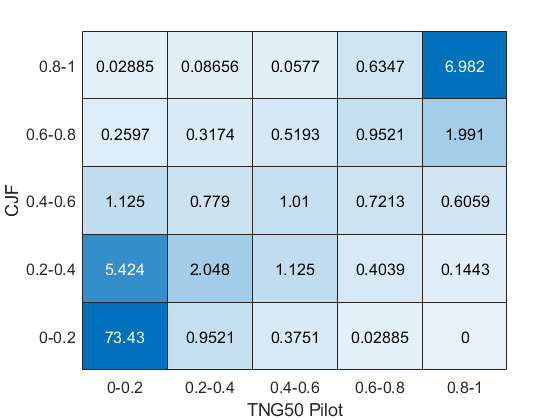


figure
edj=0:0.2:1;
edj(end)=1.01;
len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scoreCJF50>=edj(i) & scoreCJF50<edj(i+1)) & ...
            (score50>=edj(j) & score50<edj(j+1)) );
    end
end
 
 cdata=cdata./length(scoreCJF50).*100;
 lab={'0-0.2' '0.2-0.4' '0.4-0.6' '0.6-0.8' '0.8-1'};
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 7])
colorbar('off')
ht.xlabel('TNG50 Pilot')
ht.ylabel('CJF')
ht.FontSize=12;

bins along the secondary diagonal (bottom left to top right) show complete agreement :

fprintf('total agreement by bins (along secondary diagonal)= %s %% \n',num2str(trace(cdata)))

total agreement by bins (along secondary diagonal)= 84.4201 % 


This is quite a good agreement already, but what we are really after is the agreement of what is or isn't a Jellyfish. We set the JF threshold criteria to be a score of 0.8: 16 votes or more for the CJF sample and 5 & 6 votes for the TNG50 pilot project. This collapses the above matrix into this : 

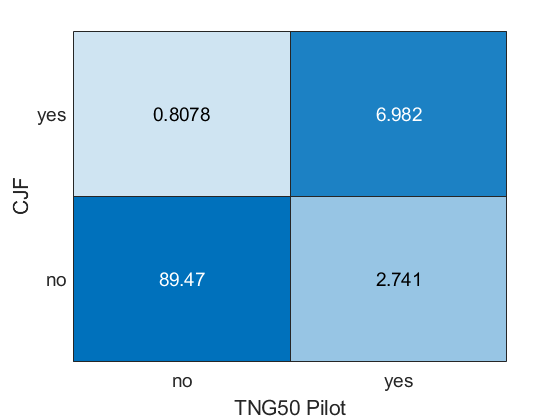


jfThresh=0.8;
jfCJF=scoreCJF50>=jfThresh;
jf50=score50>=jfThresh;



jfdata=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./sum(indMask50)*100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 8])
colorbar('off')
ht.xlabel('TNG50 Pilot')
ht.ylabel('CJF')

fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh), num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.8)= 96.4512 % 


Now we see a ~90% agreement on objects which aren't JF and ~7% agreement on what are. Overall there is ~96% agreement in the classifications. This is quite impressive.

Less than 1% of objects (28 objects) which were deemed to be JF by the CJF classifications but the expert classifications decided they wern't: Most of these (22 objects)  received 4 votes in the expert classifications. 

About 2.75% of objects (95 objects) were identified as JF by the experts but not by the CJF classifiers. Again, most (69 objects) if these recieved between 12-15 votes in the CJF classifications. 

FInal word- Within the subsample there is excellent agreement between the experts and the non-expert classification. 

It may be interesting to examine the objects for which there is a disagreement individually if we want to learn what confuses people in the classification. 

The agreement level is largely unchanged when changing the JF threshold score to 0.66 or 0.9: 

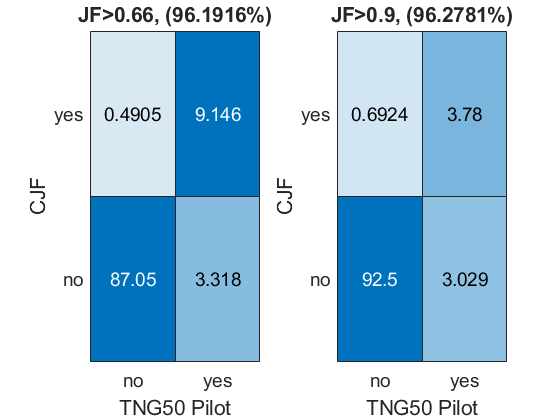

jfThresh=[0.66 0.9];

figure

for i=1:2
jfCJF=scoreCJF50>=jfThresh(i);
jf50=score50>=jfThresh(i);



jfdata(:,:,i)=[sum(jfCJF & ~jf50) , sum(jfCJF & jf50);...
    sum(~jfCJF & ~jf50) , sum(~jfCJF & jf50)]./sum(indMask50)*100;
subplot(1,2,i)

ht(i)=heatmap(["no " "yes "],["yes " "no "],jfdata(:,:,i));
ht(i).FontSize=14;
caxis([0 8])
colorbar('off')
ht(i).xlabel('TNG50 Pilot')
ht(i).ylabel('CJF')
tag=sprintf('JF>%s, (%s%%)',num2str(jfThresh(i)),num2str(jfdata(1,2,i)+jfdata(2,1,i)));
title(tag);
end

## compare TNG100 to CJF

In trying to compare to the original Yun+19 sample we already run into something strange 

% find subsample 

mask100=(objectCJF.sim=="TNG100");
indCJF100=zeros(height(object100),1)-1; % indices in CJF object table of matched objects 

for j=1:height(object100)
    subID=object100.subfind(j);
    snp=object100.snap(j);
    
    ind=find(objectCJF.snap==snp & objectCJF.subfind==subID & mask100);
    if ~isempty(ind)
        indCJF100(j)=ind;
    end
end

indMask100=indCJF100>0;


scoreCJF100=min(objectCJF.score(indCJF100(indMask100))./20,1);
score100=double(object100.score(indMask100))./5;


The size of the sample based on the catalogs in the post-processing folders is 

fprintf('size of yun+19 sample: %i \n',height(object100))

size of yun+19 sample: 3117 


This is a different number than what appears in the paper (6066 total & 2610 with gas).

The Yun+19 sample included snapshot 63 (z=0.6) which is absent from the CJF sample. The objects in the relavant snapshots (72, 84 & 99) are: 

fprintf('size of yun+19 sample in common snapshots : %i \n',sum(object100.snap~=63))

size of yun+19 sample in common snapshots : 2284 


In the paper this is  4798 total and 1898 with gas. I'm not sure why there is a difference between the flag catalogs and the paper.

When looking for the objects from the Yun+2019 sample in the CJF we find: 


fprintf('Number of objects in yun+19 sample found in CJF: %i \n',sum(indMask100) )

Number of objects in yun+19 sample found in CJF: 2142 


So there is some discrepency with the numbers but it seems that of the satellites with gas used in the paper, all are found within the CJF Sample.

There were 5 Inspectors for this project so  the possible scores are: 

aa=cat(2,(0:5)',(0:5)'./5);
disp(aa)

         0         0
    1.0000    0.2000
    2.0000    0.4000
    3.0000    0.6000
    4.0000    0.8000
    5.0000    1.0000



## Compare the JF by scores for the two projects 

In this comparison the binning is slightly different for the top bin in the two projects

- For CJF - In the top bin (0.8-1.0) we include all objects with scores higher or equal to 0.8 and lower or equal to 1.0 (as before)

- For the Yun+19 sample we include all objects with scores above 0.8 and lower or equal to one - in essence, only objects with score 1. 

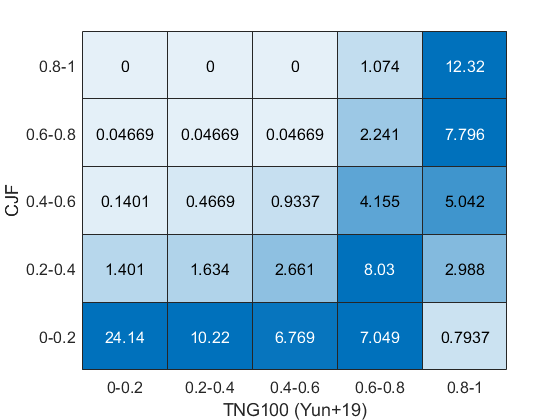

figure
edj=0:0.2:1;
edj100=edj;
edj100(end-1:end)=edj100(end-1:end)+0.01;
edjCJF=edj;
edjCJF(end)=1.01;


len=length(edj)-1;
cdata=zeros(len,len);
for i=1:len
    for j=1:len
        cdata(i,j)=sum((scoreCJF100>=edjCJF(i) & scoreCJF100<edjCJF(i+1)) & ...
            (score100>=edj100(j) & score100<edj100(j+1)) );
    end
end
 
 cdata=cdata./length(scoreCJF100).*100;
 
% imagesc(cdata)
% caxis([0 10])
% set(gca,'Ydir','normal','xtick',1:5,'xticklabel',lab,...
%     'ytick',1:5,'yticklabel',lab)
% colormap(cmap)

figure
ht=heatmap(lab,fliplr(lab),flipud(cdata));
caxis([0 7])
colorbar('off')
ht.xlabel('TNG100 (Yun+19)')
ht.ylabel('CJF')
ht.FontSize=12;

fprintf('total agreement by bin (secondary diagonal)= %s %% \n',num2str(trace(cdata)))

total agreement by bin (secondary diagonal)= 41.2698 % 


Results are very different here - there are many objects which received higher scores from the experts but lower scores from the visual classification. 

For the collapsed case (only yes no) we find that while there is good agreement on what is or isn't a JF (~81% agreement). There are quite a few objects (343) which were classified as JF by the experts but not by the CJF classifiers:

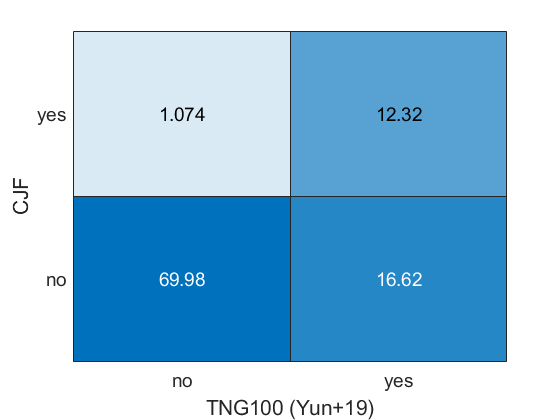



jfThresh=0.8;
jfCJF=scoreCJF100>=jfThresh;
jf100=score100>=(jfThresh+0.1);



jfdata=[sum(jfCJF & ~jf100) , sum(jfCJF & jf100);...
    sum(~jfCJF & ~jf100) , sum(~jfCJF & jf100)]./sum(indMask100)*100;
ht=heatmap(["no " "yes "],["yes " "no "],jfdata);
ht.FontSize=14;
caxis([0 20])
colorbar('off')
ht.xlabel('TNG100 (Yun+19)')
ht.ylabel('CJF')


fprintf("total agreement on what is or isn't JF (score>=%s)= %s %% \n",...
   num2str(jfThresh),num2str(jfdata(1,2)+jfdata(2,1)))

total agreement on what is or isn't JF (score>=0.8)= 82.3063 % 


For the collapsed case (only yes no) we find that while there is good agreement on what is or isn't a JF (~81% agreement). There are quite a few objects (343) which were classified as JF y the experts but not by the CJF classifiers. 

I'm not sure where this discrepency comes from or what is it's source - perhaps we were too liberal in our definitions earlier? This could acount for the difference in the shape of the votes distributions between the two samples

## Plot vote distribution

be=[0 0.2 0.4 0.6 0.79 1]

be =          0    0.2000    0.4000    0.6000    0.7900    1.0000


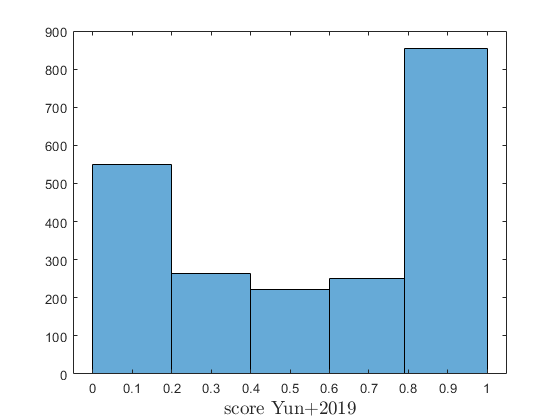


figure
histogram(score100,be)
xlabelmine('score Yun+2019');

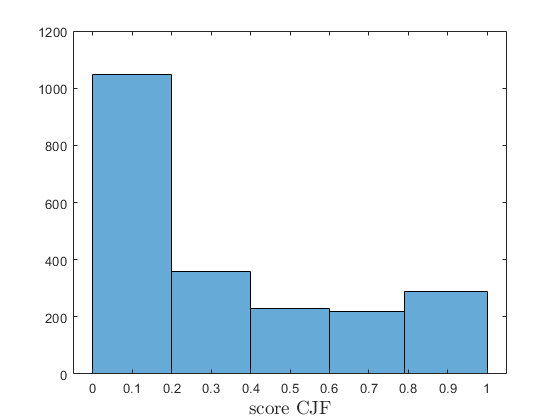




figure
histogram(scoreCJF100,be)
xlabelmine('score CJF');

Score distributions for the same objects are indeed different 

Now: score distributions 

%Generate a list of galaxies that are yes in Yun+19 but not in CJF

listMask=(~jfCJF & jf100); %index of object in matched list 

matchedInd=indCJF100(indMask100); % index in CJF object table of matched objects

listInd=matchedInd(listMask);

fid=fopen('C:\Users\eladz\Documents\workProjects\IllustrisTNG\jellyFish\yun2019Yes_cjfNo_id_list.txt','w');

fid = 3

fprintf(fid,'columns: snapshot, subfind ID (0-based), CJF score, Yun+19 score \n');
for i=1:length(listInd) 
    ind=listInd(i);
    snp=objectCJF.snap(ind);
    sim=objectCJF.sim(ind);
    score=objectCJF.score(ind);
    subID=objectCJF.subfind(ind);
    
    % check sim 
    if sim~="TNG100"
        error('wrong sim')
    end
    
    
    % check to see that the score is indeed 5 
    Yind=find(object100.snap==snp & object100.subfind==subID);
    if ~isempty(ind)
        Yscore=object100.score(Yind);
        if Yscore~=5
            error('wrong score')
        end
    else
        error('empty index')
    end
    
    % write to file 
    fmt='%2i  %9i  %2i  %1i \n';
    fprintf(fid,fmt,snp,subID,score,Yscore);
    
end

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

ans = 22

fclose(fid);

ans = 0





%  histogram(object100.score(indMask100))
%  xlabelmine('score');
%   histogram(score50.*6)
%  xlabelmine('score',7);
%  
%  histogram(objectCJF.score./20,7)
% histogram(objectCJF.score(objectCJF.sim=="TNG50")./20,7)